clear

importOptions = spreadsheetImportOptions();

importOptions.Sheet = "Tableaux2et3et4";
importOptions.VariableNames = ["Unit", "Node", "Fuel", "Pmin", "Pmax", "Rpos", "Rneg", "RU", "RD", "UT", "DT", "C", "CRpos", "CRneg", "Csu", "Pini", "Uini", "Tini"];
importOptions.VariableTypes = ["double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
importOptions.DataRange = "A3:R14";

dataC = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);

importOptions = spreadsheetImportOptions();
importOptions.Sheet = "Tableau1";
importOptions.VariableNames = ["H", "D"];
importOptions.VariableTypes = ["double", "double"];
importOptions.DataRange = "A2:B25";

dataD = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);
clear importOptions

% Standardisation des données
% min --> h
dataC.RU = dataC.RU*60;
dataC.RD = dataC.RD*60;

% Données
h = length(dataD.H);
c = length(dataC.Unit);
n = c*h;
partR = 0.05;  % Niveau de sécurité pour la réserve (pourcentage de la demande)


%% Fonction obj
% X : 24*12*5 paramètres
% X : [C1(1), C1(2), ...,  i1(1), ...,  dem1(1), ...,  Rp(1), ...,  Rn(1), ...]
%    P : puissance
%    i : état

intcon = n+1:2*n;
% Nombre params : 2*n
f_obj = @(P) sum(reshape(P(1:n), 24, 12)*dataC.C);

f_lin = [reshape((dataC.C*ones(1, h))', 1, n), ...
    zeros(1, n)];

nParam = 2*n;

%% Contrainte égalités
% Demande
D_eq = repmat(eye(h), 1, c);
bD_eq = dataD.D;

% Matrice égalité
Aeq = [D_eq, zeros(h, n)];
beq = bD_eq;

%% Contraintes inégalité
% RD
RU_ineq = eye(n);
bRU_ineq = reshape((dataC.RU*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bRU_ineq(i*h+1) = bRU_ineq(i*h+1) + dataC.Pini(i+1);
end
RU_ineq = [RU_ineq + diag(diago, -1), zeros(n)];

% RU
RD_ineq = -eye(n);
bRD_ineq = reshape((dataC.RD*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bRD_ineq(i*h+1) = bRD_ineq(i*h+1) - dataC.Pini(i+1);
end
RD_ineq = [RD_ineq + diag(diago, -1), zeros(n)];

% Réponse à la demande  : somme(Pi(k)) > D(k)
D_ineq = repmat(-eye(h), 1, c);
bD_ineq = -dataD.D;

% Réponse à la demande  : somme(Pi(k)) < D(k)
D_ineq = [D_ineq ; repmat(eye(h), 1, c)];
D_ineq = [D_ineq, zeros(2*h, n)];
bD_ineq = [bD_ineq ; dataD.D+1e-5];

% On/off : Pmin(i)*ii(k) - Pi(k) < 0
Pmin_ineq = [-eye(n), diag(reshape((dataC.Pmin*ones(1, h))', n, 1))];   % Explication : (dataC.Pmin*ones(1, h))' : [Pmin(1) ... Pmin(1);Pmin(2) ... Pmin(2) ; .. ; Pmin(c) ... Pmin(c)]
bmin_ineq = zeros(n, 1);

% On/off : Pi(k) - Pmax(i)*ii(k) < 0.001
Pmax_ineq = [eye(n), -diag(reshape((dataC.Pmax*ones(1, h))', n, 1))];
bmax_ineq = 0.001*ones(n, 1);

% Matrices finales Puiss et état
Aineq = [RU_ineq ; RD_ineq ; Pmin_ineq ; Pmax_ineq; D_ineq];
bineq = [bRU_ineq ; bRD_ineq ; bmin_ineq ; bmax_ineq; bD_ineq];

%% Bornes
lb = zeros(nParam, 1);
ub = [reshape((dataC.Pmax*ones(1, h))', n, 1); ones(n, 1)];

% Options
opt_ga = optimoptions("ga");

% Appel ga
[xsol, fval] = ga(f_obj, nParam, Aineq, bineq, [], [], lb, ub, '', intcon, opt_ga)

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
but constraints are not satisfied.


xsol =   144.5721  112.6306   50.3275   87.4043  110.5067   79.1396    0.0013   69.3085  149.7174  122.0544  110.9030   46.4877  112.2656   87.5701    0.1636   73.2157  106.2571  116.4162   92.5237  107.8251  121.8952    1.8955  121.8965   48.9096  140.9569   91.4015  111.7992   84.0949  137.9943   83.5025  140.5715   35.4445  150.1358  120.9222  109.9060    0.0112   84.7587   99.9240  112.3038  109.4413   90.7458   85.8866  127.1917    7.1941  127.1940  150.3682  148.5844   42.7915  347.1189   82.7604


fval = 6.1199e+05

Psol = reshape(xsol(1:n), 24, 12)

Psol =   144.5721  140.9569  347.1189  179.9994   52.2568  142.8403  140.8564  392.5928    0.1639    0.2150  194.2647   39.9976
  112.6306   91.4015   82.7604  236.4362   31.5960  141.0360    0.4866  267.0360  212.6582  299.9994   14.2645  179.5109
   50.3275  111.7992  179.8852  250.6491   25.9688   70.0724    0.0116  167.5836  330.8882    0.0182  173.2308  229.8646
   87.4043   84.0949  250.8821  186.6049    0.0193   67.3170   85.7610  115.0983  247.8474  299.9963  138.7685    0.0009
  110.5067  137.9943    0.0734    7.0237   19.8222  106.4406  105.4695  349.2223    0.0071  299.1791  188.0695  239.9869
   79.1396   83.5025   76.8909   24.2035   37.7001   60.1314  118.9152  102.4550  367.3435  299.9995  132.6200  207.3998
    0.0013  140.5715  285.3653  206.1021   59.4109  101.9476   99.7408  215.8829  348.4051  299.5268    0.0186  204.3963
   69.3085   35.4445  212.5053  386.1083   27.8056  124.4090   78.0242  305.4714  373.7645  299.9736  152.0149  214.6010
  149.7174  150.1358  260

dataC.C

ans =    13.3200
   13.3200
   20.7000
   20.9300
   26.1100
   10.5200
   10.5200
    6.0200
    5.4700
         0


% Contrainte RU
RU_ineq*xsol(1:2*n)' - bRU_ineq

ans =   -51.4279
 -151.9415
 -182.3032
  -82.9231
  -96.8977
 -151.3671
 -199.1383
  -50.6929
  -39.5911
 -147.6630


% Contrainte RD
RD_ineq*xsol(1:2*n)' - bRD_ineq

ans =  -188.5721
  -88.0585
  -57.6968
 -157.0769
 -143.1023
  -88.6329
  -40.8617
 -189.3071
 -200.4089
  -92.3370


% Contrainte Demande
D_eq*xsol(1:n)' - bD_eq

ans =    -0.0002
    0.0015
   -0.0008
    0.0001
    0.0001
    0.0009
   -0.0006
    0.0009
   -0.0010
   -0.0018


% Contrainte on/off
[Pmin_ineq ; Pmax_ineq]*xsol(1:2*n)' - [bmin_ineq ; bmax_ineq]

ans =  -114.1721
  -82.2306
  -19.9275
  -57.0043
  -80.1067
  -48.7396
   -0.0013
  -38.9085
 -119.3174
  -91.6544


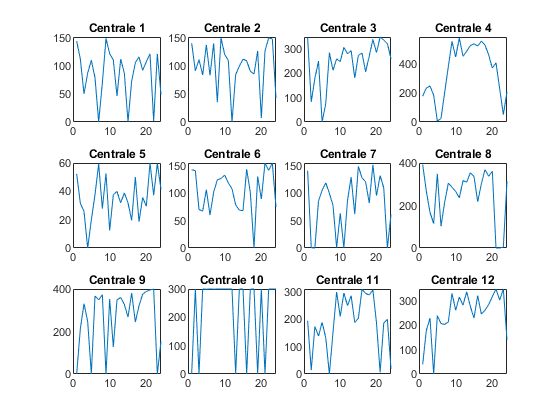

% Plot puissances
for i=1:c
    subplot(3, 4, i)
    plot(1:h, Psol(:, i))
    title(sprintf("Centrale %i", i))
    ylim([0 dataC.Pmax(i)])
end

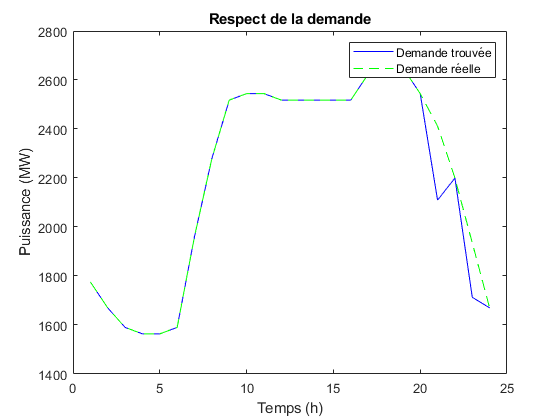


% Plot demande
subplot(111)
plot(1:h, sum(Psol, 2), '-b', 1:h, dataD.D, '--g')
title("Respect de la demande")
legend(["Demande trouvée", "Demande réelle"])
xlabel("Temps (h)")
ylabel("Puissance (MW)")